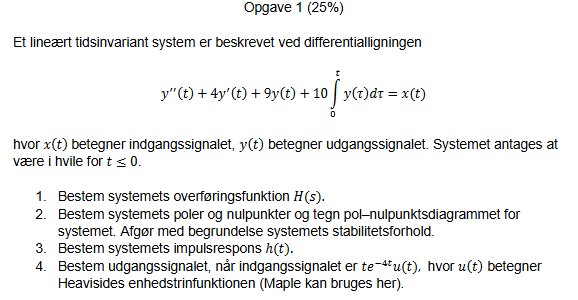

clear all; clc;

### 1. Bestem systemets overføringsfunktion 𝐻(𝑠).

disp('================================================================');

disp('DELOPGAVE 1: BESTEM SYSTEMETS OVERFØRINGSFUNKTION H(s)');

DELOPGAVE 1: BESTEM SYSTEMETS OVERFØRINGSFUNKTION H(s)


disp('================================================================');

disp(' ');


a = [1, 4, 9, 10];    % Nævner koefficienter: s³ + 4s² + 9s + 10
b = [1, 0];           % Tæller koefficienter: s

[num_tf, den_tf, tf_forklaring] = ElektroMatBibTrinvis.diffLigningTilOverfoeringsfunktionMedForklaring(b, a);

===== KONVERTERING AF DIFFERENTIALLIGNING TIL OVERFØRINGSFUNKTION =====
 
TRIN 1: Identificer differentialligningen
Vi starter med koefficienterne for differentialligningen.
   a = [1, 4, 9, 10] (output koefficienter)
b = [1, 0] (input koefficienter)
 
TRIN 2: Opskriv differentialligningen
Differentialligningen har følgende form:
   a_0 · y^(3) + a_1 · y^(2) + a_2 · y^(1) + a_3 · y^(0) = b_0 · x^(1) + b_1 · x^(0)
 
TRIN 3: Tag Laplacetransformationen af begge sider
Vi anvender Laplacetransformationen på hele ligningen under antagelse af nulbetingelser.
   L{y^(n)} = s^n·Y(s) - s^(n-1)·y(0) - ... - y^(n-1)(0)
 
TRIN 4: Antag nulbetingelser
Vi antager at alle startbetingelser er nul: y(0) = y'(0) = ... = y^(n-1)(0) = 0.
   Dette giver: L{y^(n)} = s^n·Y(s)
 
TRIN 5: Opskriv ligningen i Laplace-domæne
Efter Laplacetransformation får vi:
   a_0 · s^3 · Y(s) + a_1 · s^2 · Y(s) + a_2 · s^1 · Y(s) + a_3 · s^0 · Y(s) = b_0 · s^1 · X(s) + b_1 · s^0 · X(s)
 
TRIN 6: Isolér overføringsfunktionen
V


% Vis overføringsfunktionen symbolsk
syms s;
H_s = poly2sym(num_tf, s) / poly2sym(den_tf, s);

disp(' ');

disp('SVAR PÅ DELOPGAVE 1:');

SVAR PÅ DELOPGAVE 1:


disp('====================');

disp(['H(s) = ' char(H_s)]);

H(s) = s/(9*s + 4*s^2 + s^3 + 10)


disp(' ');

### 2. Bestem systemets poler og nulpunkter og tegn pol–nulpunktsdiagrammet for systemet. Afgør med begrundelse systemets stabilitetsforhold.

disp('================================================================');

disp('DELOPGAVE 2: POLER, NULPUNKTER OG STABILITET');

DELOPGAVE 2: POLER, NULPUNKTER OG STABILITET


disp('================================================================');

disp(' ');


disp('Udfører pol-nulpunktsanalyse med ElektroMatBibTrinvis...');

Udfører pol-nulpunktsanalyse med ElektroMatBibTrinvis...


disp(' ');

===== POL-NULPUNKTSANALYSE AF OPGAVE 1: INTEGRO-DIFFERENTIALSYSTEM =====
 
TRIN 1: Identificer overføringsfunktionen
Vi starter med systemets overføringsfunktion H(s).
   H(s) = s/(9*s + 4*s^2 + s^3 + 10)
 
TRIN 2: Definér poler og nulpunkter
Poler er rødder af nævnerpolynomiet (hvor H(s) → ∞). Nulpunkter er rødder af tællerpolynomiet (hvor H(s) = 0).
 
TRIN 3: Find nulpunkter
Nulpunkter findes ved at løse tællerpolynomiet = 0.
   Tæller: s = 0
 
TRIN 4: Resultater - nulpunkter
Vi har beregnet følgende nulpunkter:
   Nulpunkter:
z1 = 0.000000 (reel)
 
TRIN 5: Find poler
Poler findes ved at løse nævnerpolynomiet = 0.
   Nævner: 9*s + 4*s^2 + s^3 + 10 = 0
 
TRIN 6: Resultater - poler
Vi har beregnet følgende poler:
   Poler:
p1 = -1.000000 ± j2.000000 (kompleks pol par)
p2 = -1.000000 ± j2.000000 (kompleks pol par)
p3 = -2.000000 (reel pol)
 
TRIN 7: Analysér systemets stabilitet
Et LTI-system er stabilt hvis alle poler ligger i venstre halvplan (negative realdele).
   Vi undersøger real

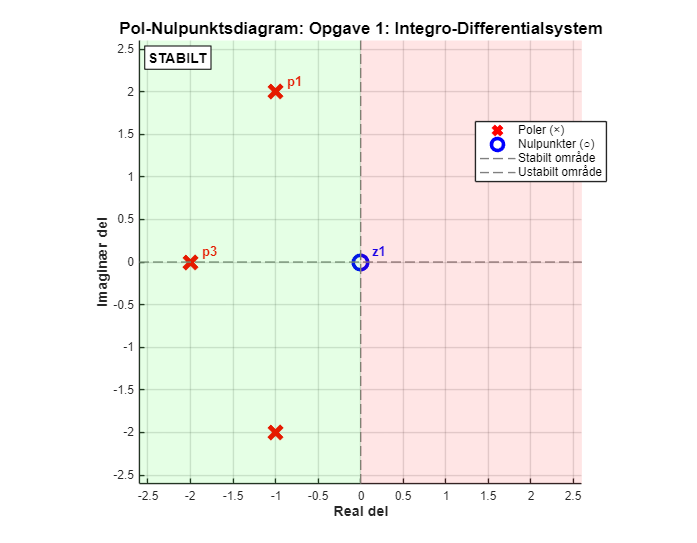

TRIN 10: Sammenfatning af pol-nulpunktsanalyse
Systemets vigtigste karakteristika:
   SAMMENFATNING:
Antal poler: 3
Antal nulpunkter: 1
Stabilitet: STABILT
System orden: 3
 
RESULTAT:
   Pol-nulpunktsanalyse færdig. System er STABILT
 
===== AFSLUTTET: POL-NULPUNKTSANALYSE AF OPGAVE 1: INTEGRO-DIFFERENTIALSYSTEM =====
 



[poler, nulpunkter, stabilitet, forklaringsOutput] = ...
    ElektroMatBibTrinvis.polNulpunktsDiagramMedForklaring(b, a, 'Opgave 1: Integro-Differentialsystem');

### 3. Bestem systemets impulsrespons ℎ(𝑡).

disp('================================================================');

disp('           DELOPGAVE 3 - SYSTEMETS IMPULSRESPONS');

           DELOPGAVE 3 - SYSTEMETS IMPULSRESPONS


disp('================================================================');

disp(' ');


syms t;

[h_t, impuls_forklaring] = ElektroMatBibTrinvis.inversLaplaceMedForklaring(H_s, s, t);

===== INVERS LAPLACETRANSFORMATION =====
 
TRIN 1: Identificer den oprindelige funktion
Vi starter med at identificere Laplace-transformationen, som skal konverteres tilbage til tidsdomænet.
   F(s) = s/(9*s + 4*s^2 + s^3 + 10)
 
TRIN 2: Identificer funktionstypen som en rationel funktion
Funktionen er en rationel funktion, der kan opløses i partialbrøker.
   F(s) = s/(9*s + 4*s^2 + s^3 + 10)
 
TRIN 3: Brug partiel brøkopløsning
Vi opløser den rationelle funktion i en sum af simplere brøker.
   F(s) = A₁/(s-p₁) + A₂/(s-p₂) + ... + B₁/((s-q₁)²+r₁²) + ...
 
TRIN 4: Beregn partialbrøkopløsning
Vi finder residuerne og polerne:
   Antal poler: 3
Polerne er rødder af nævnerpolynomiet
 
TRIN 5: Resultater af partialbrøkopløsning
Vi har fundet følgende poler og residuer:
   Poler og residuer:
p1 = -1.000000 ± j2.000000, residue = 0.200000 ± j-0.150000
p2 = -1.000000 ± j2.000000, residue = 0.200000 ± j0.150000
p3 = -2.000000, residue = -0.400000
 
TRIN 6: Anvend invers transformation på hver de

### 4. Bestem udgangssignalet, når indgangssignalet er 𝑡𝑒ି ସ௧ 𝑢(𝑡), hvor 𝑢(𝑡) betegner Heavisides enhedstrinfunktionen (Maple kan bruges her)

disp('================================================================');

disp('         DELOPGAVE 4 - BEREGN UDGANGSSIGNAL y(t)');

         DELOPGAVE 4 - BEREGN UDGANGSSIGNAL y(t)


disp('================================================================');

disp(' ');


syms s t;
X_s = 1/(s + 4)^2;                          % Input: L{te^(-4t)u(t)}

[y_t, udgang_forklaring] = ElektroMatBibTrinvis.beregnUdgangssignalMedForklaring(H_s, X_s, s, t);

===== BEREGNING AF UDGANGSSIGNAL =====
 
TRIN 1: Identificer systemet og indgangssignalet
Vi starter med at identificere systemets overføringsfunktion og indgangssignalets Laplacetransformation.
   H(s) = s/(9*s + 4*s^2 + s^3 + 10)\nX(s) = 1/(s + 4)^2
 
TRIN 2: Beregn udgangssignalets Laplacetransformation
I frekvensdomænet er udgangssignalet produktet af overføringsfunktionen og indgangssignalet.
   Y(s) = H(s) · X(s) = s/((s + 4)^2*(9*s + 4*s^2 + s^3 + 10))\nForenklet: Y(s) = s/((s + 4)^2*(9*s + 4*s^2 + s^3 + 10))
 
TRIN 3: Forbered partialbrøkopløsning
For at finde den inverse Laplacetransformation, skal vi først udføre en partialbrøkopløsning.
   Y(s) = s / (s + 4)^2*(9*s + 4*s^2 + s^3 + 10)
 
TRIN 4: Partialbrøkopløsning
Partialbrøkopløsningen er kompleks og kræver symbolsk beregning.
   Vi fortsætter med direkte invers Laplacetransformation.
 
===== INVERS LAPLACETRANSFORMATION =====
 
TRIN 1: Identificer den oprindelige funktion
Vi starter med at identificere Laplace-transformat